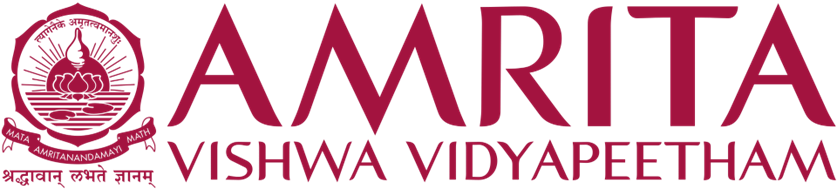

# `22MAT220   MATHEMATICS FOR COMPUTING 3 `

***Batch : AIE -C***

***Team 7***

-------------------------------------------------------------------

**G Prajwal Priyadarshan  -  CB.SC.U4AIE24214**

**Kabilan K               -  CB.SC.U4AIE24224**

**Kishore B                         -  CB.SC.U4AIE24227**

**Rahul L S                          - CB.SC.U4AIE24248**

-------------------------------------------------------------------

# **Optimizing House Price Prediction Using Lasso and Ridge Regression with ADMM-Based Regularization**

### **Introduction : **

This project aims to predict house sale prices using supervised regression models, specifically Lasso (L1) and Ridge (L2) regression. While linear regression is widely used to model relationships between input features and a target variable, it often suffers from overfitting when there are many features or high correlations among them. To overcome this,* Ridge regression* applies an L2 penalty on the squared magnitude of coefficients, while* Lasso regression* uses an L1 penalty based on their absolute values, both improving predictive performance and model generalization. These methods are framed within convex optimization, a powerful approach used in various fields, and are efficiently solved here using the Alternating Direction Method of Multipliers (ADMM), which breaks the optimization problem into smaller, more manageable subproblems.

### **Problem Statement:**

This project focuses on building models to predict Melbourne house prices using input features while minimizing error and controlling model complexity. To address issues of overfitting and handling large datasets, regularization techniques are applied, specifically Ridge and Lasso regression, which penalize the regression function to improve generalization. The study further compares these approaches by implementing them with the Alternating Direction Method of Multipliers (ADMM), which efficiently solves the optimization problems by decomposing them into simpler subproblems.

### Dataset Description:

Dataset was taken from kaggle [Click Here](https://www.kaggle.com/datasets/dansbecker/melbourne-housing-snapshot).

- **Postcode (Integer)** – Melbourne postcode (range : 3000–3999).

- **Bedroom2 (Integer)** – No of bedrooms (0–20).

- **Bathroom (Integer)** – No of bathrooms (0–8).

- **Car (Integer)** – No of car spots (0–10).

- **Landsize (Integer)** – Land size in $m^2$ (0–43,650).

- **BuildingArea (Integer)** – Building area in $m^2$ (0–~44,515).

- **Council Area (String)** – Governing council area (e.g., Yarra, Darebin).

- **YearBuilt (Integer)** – Year property built (1196–2018, mostly 1800s–2000s).

- **Latitude (Integer)** – Latitude location (-38.18 to -37.40).

- **Longitude (Integer)** – Longitude location (144.40 to 145.53).

- **RegionName (String)** – Region name (ex- Northern Metropolitan, Western).

- **Property Count (Integer)** – Number of properties in suburb (83–21,650).

- **Suburb (String)** – Locality of the house (ex -  Abbotsford, Albert Park).

- **Address (String)** – Unique address of the house.

- **Rooms (Integer)** – Number of rooms (1–10).

- **Type (String)** – Type of house (h=house, u=unit, t=townhouse).

- **Price (Integer)** – Price in AUD (85,000–9,000,000).

- **Method (String)** – Sales method (ex - S, SP, PI, PN, SA, SS, etc.).

- **SellerG (String)** – Real estate agent/agency (e.g., Biggin, Nelson).

- **Date (Date/Time)** – Date of sale (2016–2018, format dd/mm/yyyy).

- **Distance (Integer)** – Distance to CBD in km (0–50).

clc, clearvars, clf
% Load the dataset
data = readtable("melb_data.csv");

% getting the column names
columnNames = data.Properties.VariableNames;

% Looping through each column to check for missing values
for i = 1:length(columnNames)
    col = data.(columnNames{i});
    
    % Check for missing values
    numMissing = sum(ismissing(col));
    
    if numMissing > 0
        fprintf('Column "%s" has %d missing values.\n', columnNames{i}, numMissing);
    end
end

Column "Car" has 62 missing values.
Column "BuildingArea" has 6449 missing values.
Column "YearBuilt" has 5375 missing values.
Column "CouncilArea" has 1369 missing values.


Things we have to handle in Preprocessing part:

Fill up missing values in : 

- ** Car **

- ** BuildingArea**

- **YearBuilt**

- **CouncilArea**

fprintf("Size of data before preprocessing: (%d,%d)",size(data))

Size of data before preprocessing: (13579,21)

- **Filling missing values in Car column**

we fill missing car values with most common number of cars (mode of cars)

%Filling missing values for the column Car
car_mode = mode(data.Car(~isnan(data.Car))); 
data.Car(isnan(data.Car)) = car_mode;

- **Filling missing values in BuildingArea column**

We group by `Rooms` when filling BuildingArea because the number of Rooms is a natural predictor of building size, and this keeps the filled values realistic and consistent with similar houses.

sum(isnan(data.BuildingArea));
%Filling missing values for the column Building Area
uniqueRooms = unique(data.Rooms);
for i = 1:length(uniqueRooms)
    r = uniqueRooms(i);
    rowsInGroup = data.Rooms == r; %logically mask selecting houses with r rooms
    %medianBA computes median Building area for Houses with r rooms
    %ignoring null rows
    medianBA = median(data.BuildingArea(rowsInGroup & ~isnan(data.BuildingArea)));
    %missingBA identifies missing building area in that room group
    missingBA = isnan(data.BuildingArea) & rowsInGroup;
    data.BuildingArea(missingBA) = medianBA;
end

sum(isnan(data.BuildingArea));  %For Checking

- **Filling missing values in YearBuilt column**

based on the ideology that houses are built around the same time in a particular suburb

%Fillling missing values for the column Year Built
uniquesuburb = unique(data.Suburb);
for i =1:length(uniquesuburb)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);%boolean mask for particular suburb
    %medianYB computes the median built year for houses in the same suburb
    %excluding null values
    medianYB = median(data.YearBuilt(rowsinsuburb & ~isnan(data.YearBuilt)));
    missingYB = isnan(data.YearBuilt) & rowsinsuburb;% houses in the suburb with YearBuilt null values 
    data.YearBuilt(missingYB) = medianYB;
end
sum(isnan(data.YearBuilt)); %Here 18 values came so i need to fill the remaining by taking the overall median over the column
globalMedianYB = median(data.YearBuilt, 'omitnan');% median of year built excluding null values
data.YearBuilt(isnan(data.YearBuilt)) = globalMedianYB;
sum(isnan(data.YearBuilt)); %Now it will be  zero

- **Filling missing values in CouncilArea column**

Because properties within the same council area are usually in **similar geographic, economic, and planning zones**, so their building sizes tend to be in a similar range. This makes the median of that group a good estimate for missing values.

%Filling missing values for the column CouncilArea
suburbList = unique(data.Suburb);
for i = 1:length(suburbList)
    s = suburbList{i};
    rowsinsuburb = strcmp(data.Suburb, s);%boolean mask for particular suburb
    knownCouncilAreas = data.CouncilArea(rowsinsuburb & ~ismissing(data.CouncilArea));
    %This selects CouncilArea values for rows that are in this suburb and for which CouncilArea is not missing.
    if ~isempty(knownCouncilAreas)
        modeCouncil = mode(categorical(knownCouncilAreas));
        missingIdx = rowsinsuburb & ismissing(data.CouncilArea);
        data.CouncilArea(missingIdx) = cellstr(modeCouncil);
        % fills all those missing cells with the modeCouncil.
        % cellstr(modeCouncil) converts the categorical (or string) scalar to a cell string 
        % so assignment matches the table column type.
    end
end
sum(ismissing(data.CouncilArea)); %Here 7 were missing so take the global mode
globalMode = mode(categorical(data.CouncilArea(~ismissing(data.CouncilArea))));
data.CouncilArea(ismissing(data.CouncilArea)) = cellstr(globalMode);
sum(ismissing(data.CouncilArea)); % now it will be zero

data.Address  = []; % Removing the address column
data.Date = []; % Removing the date column
data.SellerG = []; % Removing the seller details

### Normalization (Z-score) of numerical columns


$$z=\frac{x-\mu }{\sigma }$$


**Where:**

- $\mu$ = mean of the data

- $\sigma$ = standard deviation of the data

- $x$ = individual data point

- $z$ = normalized value

% Split original data before one-hot encoding
numericCols = {'Rooms', 'Price', 'Distance', 'Postcode', 'Bedroom2','Bathroom', 'Car', 'Landsize', 'BuildingArea', 'YearBuilt', 'Lattitude', 'Longtitude','Propertycount'};

% Loop through each column and apply z-score normalization
for i = 1:length(numericCols)
    colName = numericCols{i};
    colData = data.(colName);
    mu = mean(colData);
    sigma = std(colData);

    % Avoid division by zero in case of zero std deviation
    if sigma ~= 0
        data.(colName) = (colData - mu) / sigma;
    else
        data.(colName) = zeros(size(colData)); % If std is 0, set to zero vector
    end
end

### ONE-HOT Encode categorical columns

we are categoriing text columns to numerical columns

dummyVars = {};
todo = {'Suburb', 'Type', 'Method', 'CouncilArea', 'Regionname'}; % these are the columns whose datatype is String

for i = 1:length(todo)
    colName = todo{i};  %todo lists categorical/text columns to convert
    catVar = categorical(data.(colName));
    encoded = dummyvar(catVar); %generates 0/1 dummy matrix for the cateogries
    % catNames = categories(catVar);
    dummyVars{end+1} = encoded;%Append the encoded matrix into dummyVars cell array.
    data.(colName) = [];%delete the original column from the table
end

oneHotEncodedMatrix = cat(2, dummyVars{:});
%horizontally concatenates all dummy matrices into one big numeric matrix (features only).

numericpart = table2array(data(:,1:end-1));
target = table2array(data(:,end));% TRAGET COLUMN IS PRICE OF HOUSE

data = [numericpart,oneHotEncodedMatrix,target];

fprintf("Size of data after preprocessing: (%d,%d)",size(data))

Size of data after preprocessing: (13579,376)

## 1. Data Splitting

here we are dividing the dataset into training and testing sets.

- **Features Matrix (****A****)**: Contains all predictor variables (columns 1 to end-1).

- **Target Vector (****b****)**: Contains the target variable, which is the house price (the last column).

- **Train-Test Split**: The data is split into a **training set** (70% of the data) and a **testing set** (the remaining 30%) 

## 2. ADMM parameters

These are the parameters that control the ADMM algorithm.

- $$ \lambda $
$: A regularization parameter that controls the strength of the penalty on the coefficients. A higher lambda leads to greater sparsity (more coefficients being set to zero).

- $$ \rho $
$: A penalty parameter that affects the convergence rate of the algorithm.

- $$ max_iter $
$: The maximum number of iterations the algorithm will run.

- $$ tol $$ : The convergence tolerance. The algorithm stops when the change in the solution falls below this value.

## 3. The lasso_admm Function

This function is the core of your model, implementing the ADMM algorithm to solve the Lasso problem.

**The Objective Function**


$$$$
\min_{x} \left( \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|x\|_1 \right)
$$
$$


- The first term, $$$
\|Ax-b\|_2^2
$$
$, is the **squared L2 norm** (equivalent to Mean Squared Error), which measures the model's prediction accuracy.

- The second term, $$ \lambda ||x||_1 $$, is the **L1 regularization penalty**, which encourages coefficients to be zero.

**Constrained form for ADMM :**


$$$$
\min_{x, z} \left( \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|z\|_1 \right) 
\quad \text{s.t.} \quad x = z
$$
$$


**Augumented Langrangian**


$$$$
\mathcal{L}_\rho(x, z, u) = \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|z\|_1 
+ \frac{\rho}{2} \|x - z + u\|_2^2 
$$
$$


**ADMM Iterative Updates**

The algorithm works by iteratively updating three variables until convergence.

**X update :**


$$%% X-update derivation (LaTeX)


$$
x^{k+1} = \arg\min_{x} \left( \frac{1}{2}\|Ax - b\|_2^2 
+ \frac{\rho}{2}\|x - z^k + u^k\|_2^2 \right)
$$

$$
\nabla_x : \; A^\top(Ax - b) + \rho(x - z_k + u_k) = 0
$$

$$
(A^\top A + \rho I)x = A^\top b + \rho(z_k - u_k)
$$

$$
x_{k+1} = (A^\top A + \rho I)^{-1}\bigl(A^\top b + \rho(z_k - u_k)\bigr)
$$
$$


**Z update**


$$$$
z^{k+1} = \arg\min_{z} \left( \lambda \|z\|_1 
+ \frac{\rho}{2}\|x^{k+1} - z + u^k\|_2^2 \right)
$$
$$



$$$$
z_{k+1} = \mathcal{S}_{\lambda/\rho}(x_{k+1} + u_k)
$$$$


The soft thresholding operator $\mathcal{S}_{\tau}(x)$  is defined as:


$$$$
\mathcal{S}_{\tau}(x) = \text{sign}(x) \cdot \max(0, |x| - \tau)
$$
$$


- $$ |x| $
$: The absolute value of the coefficient.

- $$ |x| - \tau $$: This shrinks the value. If it's negative, it's set to zero.

- $$ \text{sign}(x) $$: Retains the sign of the original coefficient.

- 
$$$$
\tau = \frac{\lambda}{\rho}
$$
$$


**U update :**


$$$$
u^{k+1} = u^k + \left(x^{k+1} - z^{k+1}\right)
$$
$$


A = data(:,1:end-1);
b = data(:,end);

g = size(A, 1);
split_index = round(0.7* g);
A_train = A(1:split_index, :);
A_test  = A(split_index+1:end, :);
b_train = b(1:split_index, :);
b_test  = b(split_index+1:end, :);

lambda = 0.1;
rho = 1.6;
max_iter = 3000;
tol  = 1e-4;
function [x,history] = lasso_admm(A,b,lambda,rho,max_iter,tol)
    [~, n] = size(A);
    z0= zeros(n, 1);
    u0 = zeros(n, 1);
    AtA = A'*A;
    Atb = A'*b;

    history.objval = zeros(max_iter,1);
    history.primal_res = zeros(max_iter,1);
    history.dual_res = zeros(max_iter,1);

    i=1;
    while i<max_iter
        x1 = inv(AtA + rho*eye(n))*(Atb + rho*(z0 - u0));
        z1 = soft_threshold(x1 + u0, lambda / rho);
        u1 = u0 + (x1 - z1);

        r_norm = norm(x1 - z1);
        s_norm = norm(rho*(z1 -z0));

        history.objval(i) = 0.5*norm(A*x1-b)^2 + lambda*norm(z1,1);
        history.primal_res(i) = r_norm;
        history.dual_res(i) = s_norm;

        if (r_norm <= tol && s_norm <=tol)
            fprintf("Converged at %dth iteration\n",i)
            history.objval = history.objval(1:i);
            history.primal_res = history.primal_res(1:i);
            history.dual_res = history.dual_res(1:i);
            break
        end
        z0 = z1;
        u0 = u1;
        i=i+1;
    end
    x= x1;
end

function z = soft_threshold(x, tau)
    z = sign(x) .* max(abs(x) - tau, 0);
end
disp("Lasso Regression")

Lasso Regression


[x,history] = lasso_admm(A_train,b_train,lambda,rho,max_iter,tol);

Converged at 307th iteration


y = A_test * x;
rmse = sqrt(mean((y - b_test).^2));
mae = mean(abs(y - b_test));
disp(['RMSE: ', num2str(rmse)]);

RMSE: 0.72265


disp(['MAE: ', num2str(mae)]);

MAE: 0.39014


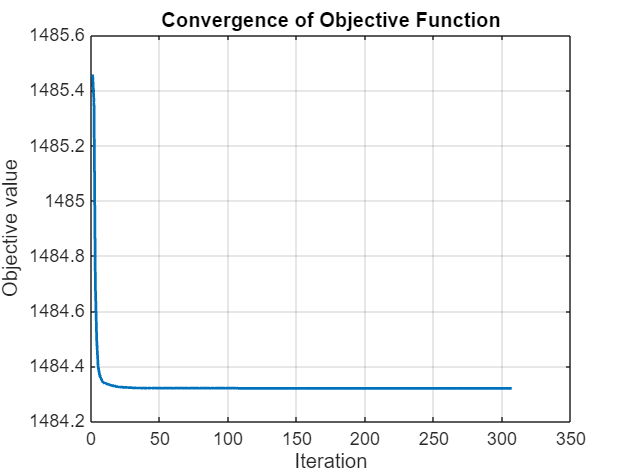

% Plot objective value
figure;
plot(history.objval, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Objective value');
title('Convergence of Objective Function');
grid on;

## 4. The ridge_admm Function

This function is the core of your model, implementing the ADMM algorithm to solve the Lasso problem.

**The Objective Function**


$$$$
\min_{x} \left( \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|x\|_2^2\right)
$$
$$


- The first term, $$$
\|Ax-b\|_2^2
$$
$, is the **squared L2 norm** (equivalent to Mean Squared Error), which measures the model's prediction accuracy.

- The second term, $$ \lambda ||x||_2^2 $$, is the **L2 regularization penalty**, which encourages coefficients close to zero.

**Constrained form for ADMM :**


$$$$
\min_{x, z} \left( \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|z\|_2^2 \right) 
\quad \text{s.t.} \quad x = z
$$
$$


**Augumented Langrangian**


$$$$
\mathcal{L}_\rho(x, z, u) = \frac{1}{2} \|Ax - b\|_2^2 + \lambda \|z\|_2^2 
+ \frac{\rho}{2} \|x - z + u\|_2^2 
$$
$$


**ADMM Iterative Updates**

The algorithm works by iteratively updating three variables until convergence.

**X update :**


$$%% X-update derivation (LaTeX)


$$
x^{k+1} = \arg\min_{x} \left( \frac{1}{2}\|Ax - b\|_2^2 
+ \frac{\rho}{2}\|x - z^k + u^k\|_2^2 \right)
$$$$



$$$$
\nabla_x : \; A^\top(Ax - b) + \rho(x - z_k + u_k) = 0
$$$$



$$$$
(A^\top A + \rho I)x = A^\top b + \rho(z_k - u_k)
$$$$



$$$$
x_{k+1} = (A^\top A + \rho I)^{-1}\bigl(A^\top b + \rho(z_k - u_k)\bigr)
$$$$


**Z update**


$$$$
z^{k+1} = \arg\min_{z} \left( \lambda \|z\|_2^2 
+ \frac{\rho}{2}\|x^{k+1} - z + u^k\|_2^2 \right)
$$
$$



$$\[
2\lambda z + \rho\big(z - x^{k+1} - u^k\big) = 0
\]
$$



$$\[
(2\lambda + \rho)z = \rho\big(x^{k+1} + u^k\big)
\]$$



$$$$
z^{k+1} = \frac{\rho}{2\lambda + \rho}\,\left(x^{k+1} + u^k\right)

$$$$


**U update :**


$$$$
u^{k+1} = u^k + \left(x^{k+1} - z^{k+1}\right)
$$
$$


function [x,history] = ridge_admm(A,b,lambda,rho,max_iter,tol)

Ridge Regression


    [~, n] = size(A);

Converged at 52th iteration

    z0= zeros(n, 1);
    u0 = zeros(n, 1);
    AtA = A'*A;
    Atb = A'*b;
    i=1;

RMSE: 0.72156


MAE: 0.38964


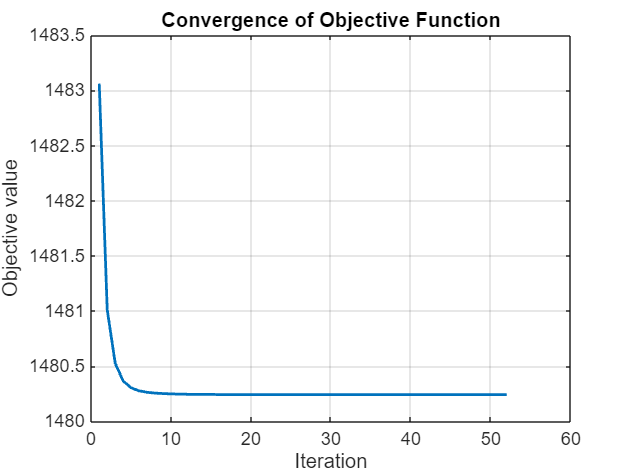

    history.objval = zeros(max_iter,1);
    history.primal_res = zeros(max_iter,1);
    history.dual_res = zeros(max_iter,1);
    while i<max_iter
        x1 = inv(AtA + rho*eye(n))*(Atb + rho*(z0 - u0));
        z1 = rho*(x1+u0)/(2*lambda + rho);
        u1 = u0 + (x1 - z1);


        r_norm = norm(x1 - z1);
        s_norm = norm(rho*(z1-z0));

        history.objval(i) = 0.5*norm(A*x1-b)^2 + lambda*norm(z1,2)^2;
        history.primal_res(i) = r_norm;
        history.dual_res(i) = s_norm;

        if (r_norm <= tol && s_norm <=tol)
            fprintf("Converged at %dth iteration",i)
            history.objval = history.objval(1:i);
            history.primal_res = history.primal_res(1:i);
            history.dual_res = history.dual_res(1:i);
            break
        end
        z0 = z1;
        u0 = u1;
        i=i+1;
    end
    x= x1;
end
disp("Ridge Regression")
[x,history]= ridge_admm(A_train,b_train,lambda,rho,max_iter,tol);

y = A_test * x;
rmse = sqrt(mean((y - b_test).^2));
mae = mean(abs(y - b_test));
disp(['RMSE: ', num2str(rmse)]);
disp(['MAE: ', num2str(mae)]);

% Plot objective value
figure;
plot(history.objval, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Objective value');
title('Convergence of Objective Function');
grid on;